spectra = importdata('spectra.csv');
lamdaStart = importdata('lambda_start.csv');
lambdaDelta = importdata('lambda_delta.csv');
starNames = importdata('star_names.csv');

nObs = size(spectra, 1);
nStrs = size(spectra, 2);
lambdaEnd = lamdaStart + (nObs - 1) * lambdaDelta ;
lambda = (lamdaStart : lambdaDelta : lambdaEnd)';
lambdaPr = 656.28;
speedOfLight = 299792.458;

for i = 1 : 1 : nStrs
s = spectra (:, i);
[sHa(i), idx(i) ] = min(s);
lambdaHa = lambda(idx(i));

z (i) = (lambdaHa / lambdaPr) - 1;
speed (i) =  z (i) * speedOfLight;
end
speed = speed'

speed =   -36.5445 -100.4973  -36.5445   27.4083   27.4083  155.3139 -228.4029



movaway = starNames(z>0)'

movaway = 1×3 cell array
    {'HD5211'}    {'HD56030'}    {'HD94028'}


%movaway = movaway'

hold on
for i = 1 : 1 : nStrs
   s = spectra (:, i);
   if z(i) > 0  
   plot(lambda, s,'LineWidth', 3  );
   legend(starNames);
   else 
       plot (lambda, s, "--", 'LineWidth', 1);
   set(gcf, 'Visible', 'on');
   legend(starNames);
   end
   xlabel("Длина волны, нм");
   ylabel(['Интенсивность, эрг/см^2/с/', char(197)]);
   title('Спектры звезд');
   grid on;
   text(lamdaStart+5, 3.3*10^-13,'Паншин Артём, Б01-005' );
end

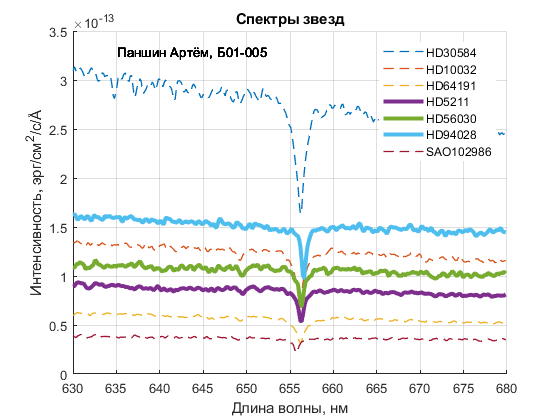

hold off
saveas(gcf, 'Spectres.png')